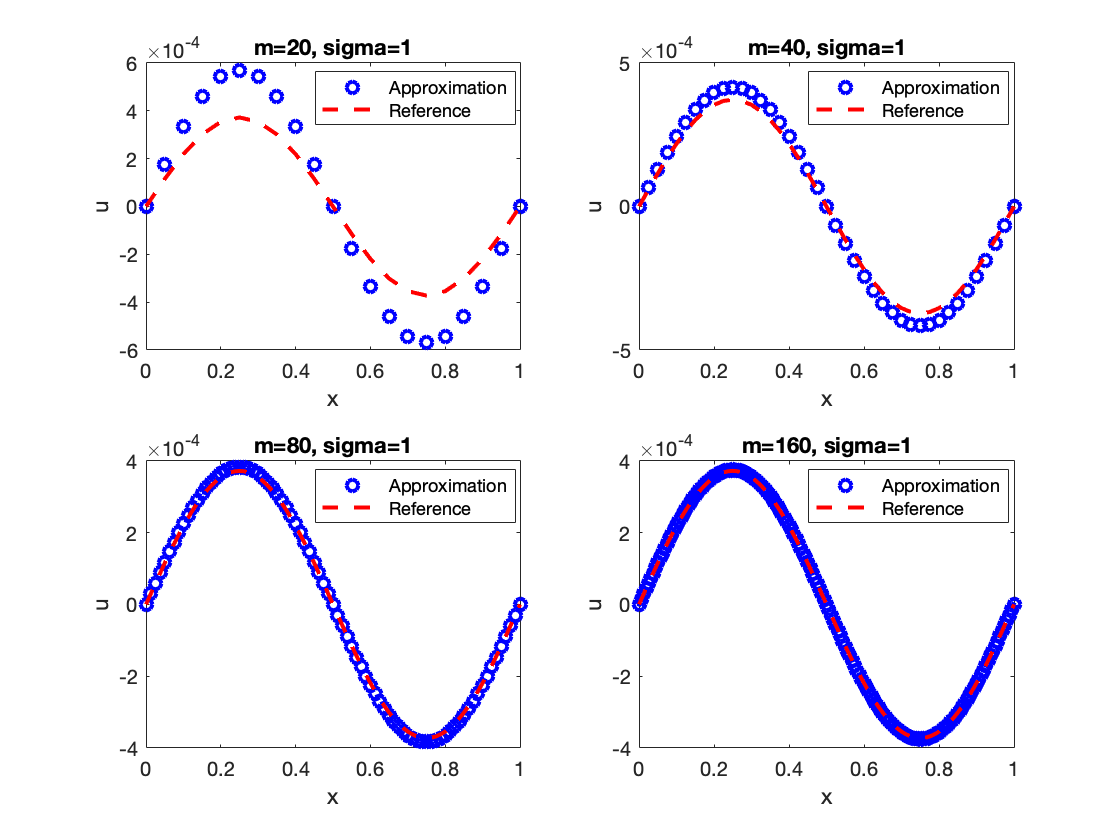

% Implementing BTCS scheme for the heat equation with periodic boundary
% condition

%spatial domain [0, 1]
a=0;
b=1;
%initial condition (periodic function)
u0=@(x) sin(2*pi*x);

T = 0.2;

err_l2dx=zeros(4,1);

order=@(e) log(e(1:end-1)./e(2:end))./log(2);

for j = 1:4
    m=2^j*10;
    %Generate the grid
    x=linspace(a,b,m+1)';
    %grid/mesh size
    dx=(b-a)/m;
    dt = dx^2;
    sigma = dt/(dx^2);
    n_t=floor(T/dt);
    u=u0(x);
    A = diag(ones(1,m)*(1+2*sigma))+diag(ones(1,m-1)*(-sigma),1)...
        +diag(ones(1,m-1)*(-sigma),-1);
    A(1,m)=-sigma;
    A(m,1)=-sigma;
    for i=1:n_t
        u(1:m)= A\u(1:m);
        u(end) = u(1);
    end
    % After the n_t steps, if we still have T-n_t*dt to arrive at the 
    % final time T.
    if T-n_t*dt > 0
        dt = T-n_t*dt;
        sigma = dt/(dx^2);
        A = diag(ones(1,m)*(1+2*sigma))+diag(ones(1,m-1)*(-sigma),1)...
        +diag(ones(1,m-1)*(-sigma),-1);
        A(1,m)=-sigma;
        A(m,1)=-sigma;
        u(1:m)= A\u(1:m);
        u(end)=u(1);
    end
    
    u_exact=exp(-4*pi^2*T)*sin(2*pi*x);
    
    subplot(2,2,j)
    plot(x, u, 'bo', 'LineWidth', 2);
    hold on
    plot(x, u_exact, 'r--', 'LineWidth', 2);
    hold off
    xlabel('x');
    ylabel('u');
    legend('Approximation', 'Reference', 'Location', 'best');
    title(['m=', num2str(m), ', sigma=', num2str(dt/dx^2)])
    
    err_l2dx(j)=norm(u-u_exact, 2)*sqrt(dx);
end


format short e
disp('Numerical errors and orders in the l_{2,dx} norm:');

Numerical errors and orders in the l_{2,dx} norm:


disp([err_l2dx, [0; order(err_l2dx)]])

   1.3931e-04            0
   3.1105e-05   2.1631e+00
   7.5536e-06   2.0419e+00
   1.8746e-06   2.0105e+00

